# `The Hovering Cube`

# `Rotation and Transformation Matricies, 3/3`

`By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`For tutoring purposes | Entry level Robotics | 11/23/2022`

`    A positional translation can be packaged with an orientation change in what is called a transformation matrix. The same rules apply where a trasformation matrix is 4x4 and can be expressed with matlab syntax as [[ R p ] ; 0 0 0 1] where p is a 3x1 vector for the positional change.`

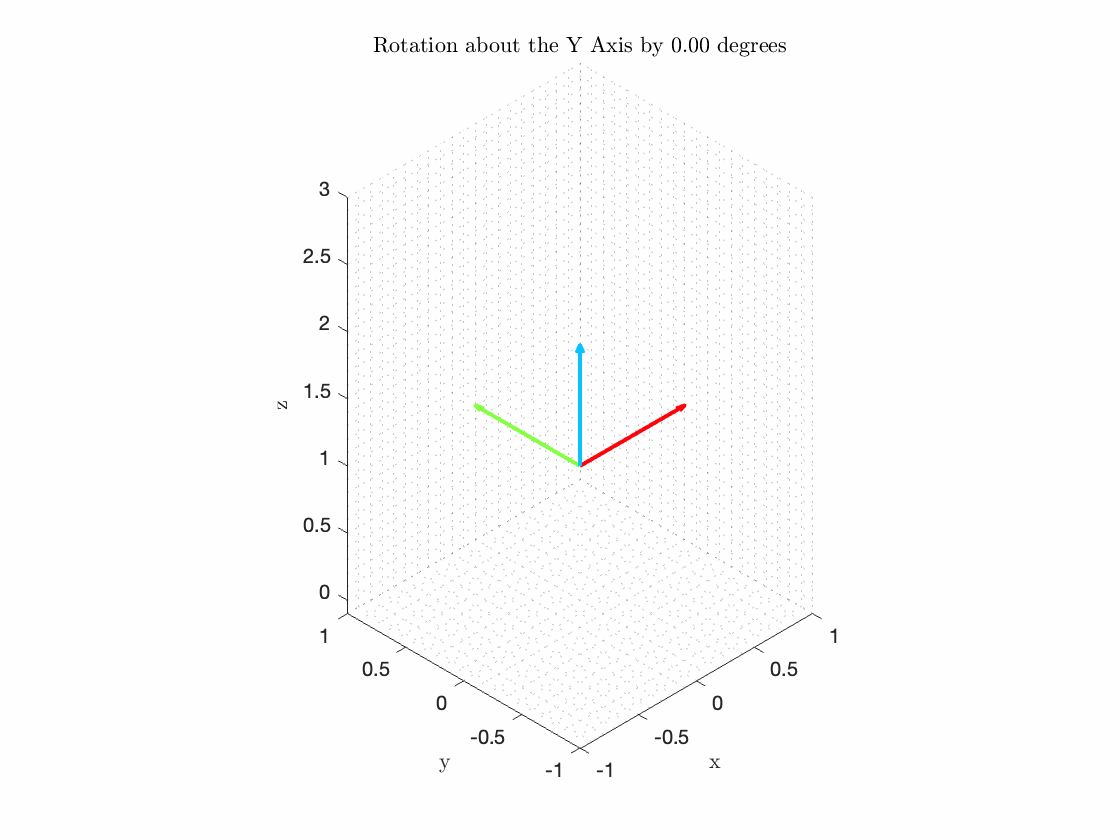

# Hovering Cube Animation 

clc; clear; close all
%Space Frame axis
%locationStart and orientationStart
p = [0 0 0]'; R = eye(3);
%TransformationMatrix Start
Tstart = [[R p];[0 0 0 1]];
endAngle = -90; time = 1;
stepSize=3;
totalSteps = -endAngle/stepSize * 4 + 4 ;
path = sin(linspace(0,2*pi,totalSteps))/2 + 1;
    for angle = 0:-stepSize:endAngle
        % New axis
        Rcurrent = rotY(angle*pi/180);
        z = path(time);
        Tlast_to_now = [[Rcurrent [0 0 0]'];[0 0 0 1]];
        Tnow = Tstart*Tlast_to_now;
        Tnow(1:3,4) = [0 0 z]';

        % New axis colors
        darkness = angle/endAngle/1.15;

        % Draw the current axis
        drawAxis2(Tnow,darkness);   %location,orientation,darkness,axisLimits)

        % Include the current angle in the title
        title(sprintf('Rotation about the Y Axis by %0.2f degrees',angle),'Interpreter','Latex');
        axis equal
        xlim([-1 1]); ylim([-1 1]); zlim([-0.1 3]);
        saveFrame('animation.gif',time)
        time = time + 1;
        clf
    end
    Rcurrent = rotY(-90*pi/180);
    Tstart = [[Rcurrent [0 0 0]'];[0 0 0 1]];
    j=2;
    for angle = 0:-stepSize:endAngle
        Rcurrent = rotZ(angle*pi/180);
        z = path(time);
        Tlast_to_now = [[Rcurrent [0 0 0]'];[0 0 0 1]];
        Tnow = Tstart*Tlast_to_now;
        Tnow(1:3,4) = [0 0 z]';
        darkness = angle/endAngle/1.15;
        drawAxis2(Tnow,darkness);   %location,orientation,darkness,axisLimits)
        title(sprintf('Rotation about the Z Axis by %0.2f degrees',angle),'Interpreter','Latex');
        axis equal
        xlim([-1 1]); ylim([-1 1]); zlim([-0.1 3]);
        saveFrame('animation.gif',time)
        time = time + 1;
        clf
    end
    Rcurrent = rotY(-90*pi/180)*rotZ(-90*pi/180);
    Tstart = [[Rcurrent [0 0 0]'];[0 0 0 1]];
    j=2;
    for angle = 0:-stepSize:endAngle
        Rcurrent = rotX(angle*pi/180);
        z = path(time);
        Tlast_to_now = [[Rcurrent [0 0 0]'];[0 0 0 1]];
        Tnow = Tstart*Tlast_to_now;
        Tnow(1:3,4) = [0 0 z]';
        darkness = angle/endAngle/1.15;
        drawAxis2(Tnow,darkness);   %location,orientation,darkness,axisLimits)
        title(sprintf('Rotation about the Z Axis by %0.2f degrees',angle),'Interpreter','Latex');
        axis equal
        xlim([-1 1]); ylim([-1 1]); zlim([-0.1 3]);
        saveFrame('animation.gif',time)
        time = time + 1;
        clf
    end
    Rcurrent = rotY(-90*pi/180)*rotZ(-90*pi/180)*rotX(-90*pi/180);
    Tstart = [[Rcurrent [0 0 0]'];[0 0 0 1]]; 
    for angle = 0:-stepSize:endAngle
        Rcurrent = rotY(angle*pi/180);
        z = path(time);
        Tlast_to_now = [[Rcurrent [0 0 0]'];[0 0 0 1]];
        Tnow = Tstart*Tlast_to_now;
        Tnow(1:3,4) = [0 0 z]';
        darkness = angle/endAngle/1.15;
        drawAxis2(Tnow,darkness);   %location,orientation,darkness,axisLimits)
        title(sprintf('Rotation about the Y Axis by %0.2f degrees',angle),'Interpreter','Latex');
        axis equal 
        xlim([-1 1]); ylim([-1 1]); zlim([-0.1 3]);
        saveFrame('animation.gif',time)
        time = time + 1;
        clf
    end

Functions 

Draw Axis Function

function drawAxis2(T,darkness)
Isometric = [-45 35.264];
%Axis Colors
f = 1+darkness; %Darkness should be from 0 to 1
color = [ [182, 2, 8]/182/f ; [59, 114, 29]/114/f ; [4, 110, 143]/143/f ];

location = T(1:3,4);
orientation = T(1:3,1:3);

%plotting 3 vectors
    hold on
    for i = 1:1:3
        vec = orientation(:,i);
        quiver3(location(1),location(2),location(3),vec(1),vec(2),vec(3),'LineWidth',2,'Color',color(i,:));
    end 
    hold off

%Viewing and Plot Settings
    view(Isometric)
    grid minor
    xlabel('x', 'Interpreter', 'Latex'),ylabel('y', 'Interpreter', 'Latex'),zlabel('z', 'Interpreter', 'Latex')
end

`Axis Limits Functions`

function axisLimits = initializeAxisLimits()
    %Initialize axis limits
    axisLimits.xmin=-0.01; axisLimits.xmax=0.1; axisLimits.ymin=-0.01; axisLimits.ymax=0.1; axisLimits.zmin=-0.01; axisLimits.zmax=0.1;
end 
function [axisLimits] = checkAxisLimits(p_now,axisLimits);
x = p_now(1); y = p_now(2) ; z = p_now(3);
%Check the current point in 3D space
%Goal of the function is to get the maximum and minimum x y z for all time
%For setting axis limits
        if x > axisLimits.xmax
            axisLimits.xmax = x; 
        elseif x < axisLimits.xmin
            axisLimits.xmin = x; 
        end 
        if y > axisLimits.ymax 
            axisLimits.ymax = y; 
        elseif y < axisLimits.ymin
            axisLimits.ymin = y; 
        end 
        if z > axisLimits.zmax
            axisLimits.zmax = z;
        elseif z < axisLimits.zmin
            axisLimits.zmin = z; 
        end 
end 

`Save Gif Function `

function saveFrame(filename,t)
%SAVE FRAME
        % delay
        pause(0.005)
        % saving the figure
        frame = getframe(gcf);
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        if t == 1 %create the file if t is 1
          imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
          %Could write a preprogrammed image here
        end 
        if t > 1 %just append to the file if its not t = 1
        imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',0.05)%,...
        %'DelayTime',0.1);
        end 
end

Rotation Matricies

function rot = rotX(a)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Z axis
    rot = [1,0,0;0,cos(a),-sin(a);0,sin(a),cos(a)];
end

function rot = rotY(b)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Y axis
    rot = [cos(b),0,sin(b);0,1,0;-sin(b),0,cos(b)];
end

function rot = rotZ(g)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Z axis
    rot= [cos(g),-sin(g),0;sin(g),cos(g),0;0,0,1];
end